## Granger Causality walkthrough

### This live script demonstrates some of the steps needed to apply Granger Causality, in the time domain, based on autoregression analysis. Granger Causality is a measure of directed connectivity.  

clear
% first load example data, make sure the data are in the current directory,
% or in the path
load('ECOG.mat') % loads channels of ECOG (implanted electrodes), 

Error using load
Unable to find file or directory 'ECOG.mat'.

% 3 channels in inferior temporal lobe;  3 channels posterior temporal
size(data)
SampRate = 500; 

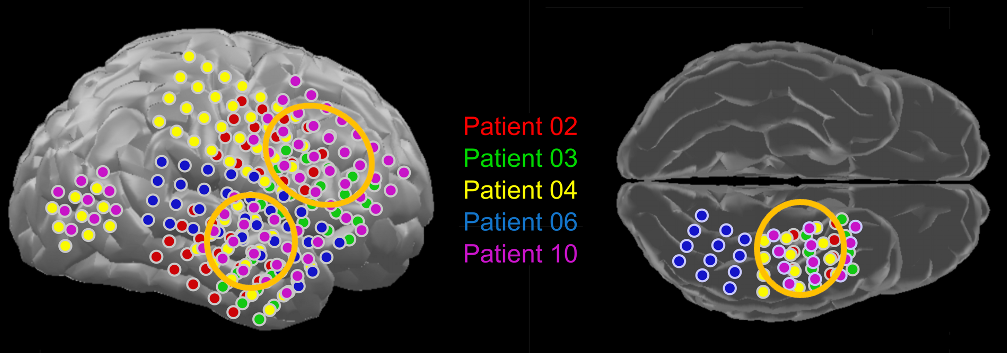

First, a brief illustration of auto-regression: we predict future data points using a regression model that uses past data points as predictors, and this model is shifted across the time series. to imagine how this works, let's use the data we have and predict future points by past points in a simple scatter plot


fig=1; 
for lag = 1:25:140 
subplot(1,6,fig), hp = plot(data(4, 1:10:end-lag), data(4, lag+1:10:end), 'ro'); hl = lsline(hp);
title(num2str(corr(data(4, 1:end-lag)', data(4, lag+1:end)')))
fig = fig+1;   
end

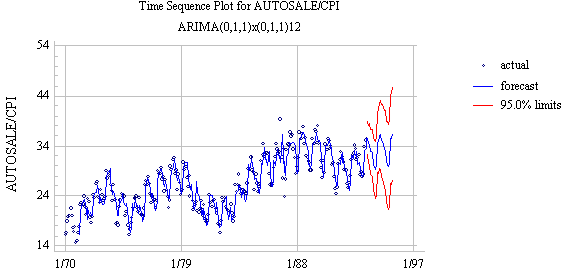

## A typical Granger causality analysis - in the time domain

The following wo steps are interactive and iterative, you may want to change many paraneters and see what they do 

warning('off')
[bic,aic] = aks_find_model_order(data,2,19)

 Figure out if data are covariance stationary = must have NO "unit root"  A time series has a unit (one) root if 1 is a root (solution) of the       

 autoregressive equation that describes the time series. Such a process is non-stationary. 

  We test for stationarity with the Augmented Dickey-Fuller test

modelorder = 14
uroot = aks_check_covariance_stationarity(data, modelorder)

It is typical for brain data to be non-stationary, so we often need to do a transformation tha keeps the dynamics intact but creates stationarity

data_z = z_norm(data); % z-transform
uroot = aks_check_covariance_stationarity(data_z, modelorder)

data_white = data_z+rand(size(data_z)); % whitening (adding white noise)
uroot = aks_check_covariance_stationarity(data_white, modelorder)

Now do the actual granger causality

[res,RSS1] = aks_granger_regress_as(data_white,modelorder);

res.gc % p-values

res.fs % F-values ('significance")

log(res.fs)  % magnitude of the connectivity

[GC,FS] = aks_findsignificance(res.gc,res.fs,0.05,1); % threshold results by "significance"

% plot results: 
figure, 
aks_plotcausality(res.fs,2);


% extract more gglobal meausres of causal density and flow

[cd,cdw] = aks_causaldensity(GC,FS)

[flow] = aks_causalflow(GC,FS);

% compare with coherence
[Cxy, F] = mscohere(data_white(1,:)',data_white(4,:)', [], 1, 700, 500);
figure, plot(F,Cxy), xlabel('frequency'), ylabel ('coherency between chans 1 and 4'), 
title ('coherency plot')